## **Lehrprogramm Robotertechnik**

**Eine Ausarbeitung von Mika Grüner, Luka Hrstic, Lukas Pelz und Marie Winkler**

Dieses Lehrprogramm zeigt verschiedene Möglichkeiten, wie man die Orientierung eines Körpers im dreidimensionalen Raum beschreiben kann:

- Richtungskosinusmatrix (RCM)

- Euler-Winkel (EW)

- Euler-Rodrigues-Parameter (ERP)

- Quaternionen

Es werden jeweils Vor- und Nachteile, numerische Aspekte, Rechenaufwand sowie Visualisierungen und Umrechnungen gezeigt.

Zur Ausführung dieses Lehrprogramms werden die Toolboxen **"Robotics Toolbox"** von Peter Corke sowie **"Aerospace Toolbox"** benötigt. Ob diese (erfolgreich) installiert sind, kann mit dem folgenden Codeblock überprüft werden.

 
x1 = contains(struct2array(ver), 'Aerospace Toolbox');
x2 = contains(struct2array(ver), 'Robotics Toolbox for MATLAB');
missingTb = strings(0);
if ~x1
    missingTb = [missingTb,"Aerospace Toolbox"];
end
if ~x2
    missingTb = [missingTb,"Robotics Toolbox for MATLAB"];
end
if size(missingTb)
    fprintf("Es fehlen folgende Toolboxen:" + newline);
    fprintf("- %s" + newline,missingTb);
else
    fprintf("Alle benötigten Toolboxen sind verfügbar!");
end

Es fehlen folgende Toolboxen:


- Aerospace Toolbox


Im Live-Script befinden sich immer wieder die folgenden Bedienelemente. Oft sind sie mit Standardparametern vordefiniert, bieten Ihnen aber die Möglichkeit selber zu experimentieren. Durch einen Klick auf den Run Button wird nur die aktuelle Section ausgeführt.

 
% Dies ist ein Codeblock - ein Codeblock kann durch Klick auf den Run Button ausgeführt werden

"one";
% Mithilfe eines Drop-Down Menüs können verschiedene Optionen angewählt werden

[0 100];
% Mithilfe eines Range-Sliders kann eine Variable vorgegeben werden

Begleitend zu den einzelnen Kapiteln, den Beschreibungen und dem Code stehen Ergänzungen in Form von kurzen "Podcasts" zu verfügung. Das Abspielen der Audiodateien kann mithilfe des folgenden Buttons aktiviert oder deaktiviert werden.

Quellenangabe zum Podcast Intro: *Podcast theme music by *[*Transistor.fm*](https://transistor.fm/?via=music)*. Learn *[*how to start a podcast*](https://transistor.fm/how-to-start-a-podcast/?via=music)* here.*

enable_audio = true    % Hier kann die Audio-Spur aktiviert oder deaktiviert werden

enable_audio = logical
   1



 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Introduction.wav');
    player = audioplayer(y, Fs);
    play(player);
end

Man kann die Audiowiedergabe mit dem Folgenden Button auch jederzeit wieder beenden, oder einfach pause(player) in die Konsole eingeben.

 

try
    pause(player);
catch
    0;
end

### 1. Mathematische Grundlagen der Rotationsdarstellungen

In diesem Abschnitt werden die vier untersuchten Methoden mathematisch beschrieben. Es folgen Definitionen und Funktionen, die im weiteren Programmablauf auch immer wieder verwendet werden.

 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_01.wav');
    player = audioplayer(y, Fs)
    play(player);
end

#### Richtungscosinusmatrix (RCM)

Die Richtungskosinusmatrix ist eine gängige Methode zur Darstellung von Rotationen im dreidimensionalen Raum. Sie besteht aus einer 3x3 Matrix, die die Transformation von einem Koordinatensystem in ein anderes beschreibt. Die Spalten repräsentieren die Einheitsvektoren des neuen Systems im alten System. Hintergründe finden sich im Skript: Robotik Teil 2 - Kinematik, S. 25.


$$\[ R = 
\left[
\begin{array}{ccc}
R_{11} & R_{12} & R_{13} \\
R_{21} & R_{22} & R_{23} \\
R_{31} & R_{32} & R_{33}

\end{array}
\right]
\]$$


Möchte man mehrere Rotationen durchführen, kann man die jeweiligen Rotationsmatritzen durch Matrix-Multiplikation miteinander verknüpfen. 


$$\[
R_{12} = R_1 \cdot R_2 =
\left[
\begin{array}{ccc}
r_{1,11} & r_{1,12} & r_{1,13} \\
r_{1,21} & r_{1,22} & r_{1,23} \\
r_{1,31} & r_{1,32} & r_{1,33}
\end{array}
\right]
\cdot
\left[
\begin{array}{ccc}
r_{2,11} & r_{2,12} & r_{2,13} \\
r_{2,21} & r_{2,22} & r_{2,23} \\
r_{2,31} & r_{2,32} & r_{2,33}
\end{array}
\right]
=
\left[
\begin{array}{ccc}
r_{1,11}r_{2,11} + r_{1,12}r_{2,21} + r_{1,13}r_{2,31} & r_{1,11}r_{2,12} + r_{1,12}r_{2,22} + r_{1,13}r_{2,32} & r_{1,11}r_{2,13} + r_{1,12}r_{2,23} + r_{1,13}r_{2,33} \\
r_{1,21}r_{2,11} + r_{1,22}r_{2,21} + r_{1,23}r_{2,31} & r_{1,21}r_{2,12} + r_{1,22}r_{2,22} + r_{1,23}r_{2,32} & r_{1,21}r_{2,13} + r_{1,22}r_{2,23} + r_{1,23}r_{2,33} \\
r_{1,31}r_{2,11} + r_{1,32}r_{2,21} + r_{1,33}r_{2,31} & r_{1,31}r_{2,12} + r_{1,32}r_{2,22} + r_{1,33}r_{2,32} & r_{1,31}r_{2,13} + r_{1,32}r_{2,23} + r_{1,33}r_{2,33}
\end{array}
\right]
\]
$$


% % % Abschnitt 1: Richtungscosinusmatrix

% Berechne die Rotationsmatrix aus Einheitsvektoren, u,v,w
function R = calculate_rotation_matrix_RCM(u,v,w)
    R = [u(1), v(1), w(1);
         u(2), v(2), w(2);
         u(3), v(3), w(3)];
end

% Berechne die Parameter u,v,w aus einer gegebenen Rotationsmatrix
function [u,v,w] = calculate_uvw_from_RCM_rotation_matrix(R)
    u = R(:,1);
    v = R(:,2);
    w = R(:,3);

end

% Berechne die Rotationsmatrix aus drei Winkeln um Z-X-Z (vgl. Eulerwinkel)
function R = angles2rcm(z1, x, z2)

    % Rotation um Z (1. Winkel)
    Rz1 = [cos(z1), -sin(z1), 0;
           sin(z1),  cos(z1), 0;
                0,       0, 1];

    % Rotation um X (2. Winkel)
    Rx  = [1,     0,       0;
           0, cos(x), -sin(x);
           0, sin(x),  cos(x)];

    % Rotation um Z (3. Winkel)
    Rz2 = [cos(z2), -sin(z2), 0;
           sin(z2),  cos(z2), 0;
                0,       0, 1];

    % Gesamtdrehmatrix
    R = Rz1 * Rx * Rz2;
end

#### Euler-Winkel (EW)

Euler-Winkler (EW) sind drei Winkel, die drei aufeinanderfolgende Drehungen beschreiben. Die Reihenfolge der Drehungen ist fest gegeben um das Problem der Nichtkommutativität von Matrixmultiplikationen zu umgehen. 

Wir verwenden im Folgenden die Reihenfolge ZXZ, angelehnt an Skript: Robotik Teil 2 - Kinematik, S. 27:

- Eine Drehung um die z-Achse um den Winkel $\phi$

- Dann eine Drehung um die gedrehte x-Achse um den Winkel $\theta$

- Abschließend eine Drehung im die gedrehte z-Achse um den Winkel $\psi$

Bemerkung: Die Reihenfolge ist in der Literatur nicht immer einheitlich, Peter Corke (Robotic Toolbox) arbeitet zum Beispiel mit ZYZ.

Mit diesen drei Drehungen lassen sich alle Orientierungen realisieren und aufgrund der vorgegebenen Winkelabfolge sind diese eindeutig definiert.

Die gesamte Richtungscosinusmatrix, die zur Rotation eines Vektors im Raum verwendet werden kann, ist folgendermaßen definiert:


$$\[ R = 
\left[
\begin{array}{ccc}
cos(\psi)cos(\phi)-sin(\psi)cos(\theta)sin(\phi) & -cos(\phi)sin(\psi)-sin(\phi)cos(\theta)cos(\psi) & sin(\phi)sin(\theta)\\
cos(\psi)sin(\phi) + cos(\phi)cos(\theta)sin(\psi) & -sin(\psi)sin(\phi) + cos(\psi)cos(\theta)cos(\phi) & -cos(\phi)sin(\theta) \\
sin(\theta)sin(\psi) & sin(\theta)cos(\psi) & cos(\theta)
\end{array}
\right]
\]$$


% % % Abschnitt 2: Euler-Winkel

% Berechne die Rotationsmatrix aus den Winkel phi theta und psi (rad)
function R = calculate_rotation_matrix_ew(phi,theta,psi)
    R = [ cos(psi)*cos(phi)-sin(psi)*cos(theta)*sin(phi),    -cos(phi)*sin(psi)-sin(phi)*cos(theta)*cos(psi),    sin(phi)*sin(theta);
          cos(psi)*sin(phi)+cos(phi)*cos(theta)*sin(psi),    -sin(psi)*sin(phi)+cos(psi)*cos(theta)*cos(phi),    -cos(phi)*sin(theta);
          sin(theta)*sin(psi),                                sin(theta)*cos(psi),                               cos(theta)        ];
end

Um aus der Richtungscosinusmatrix wieder die Winkel $\phi$, $\theta$ und $\psi$ zu berechnen kann folgende Rechenvorschrift genutzt werden. Anzumerken ist, dass diese nicht in allen Fällen gültig ist. Hierauf wird im späteren Verlauf des Lehrprogramms eingegangen.

Einer der Hauptnachteile der Euler-Winkel liegt in ihrer Nicht-Eindeutigkeit und Nicht-Invertierbarkeit. Tatsächlich ist es nicht immer möglich, genau die Euler-Winkel zu rekonstruieren, die zu einer gegebenen Rotationsmatrix geführt haben. Dies liegt insbesondere daran, dass eine bestimmte Orientierung mehreren Kombinationen von Euler-Winkeln entsprechen kann oder dass bestimmte Konfigurationen zu Singularitäten führen.

In diesem Zusammenhang definieren wir die Inverse Funktion als jene, die es ermöglicht, die Euler-Winkel aus den Koeffizienten der zuvor definierten Rotationsmatrix R zu berechnen.


$$\theta = \text{arccos}(R_{33}) \\   \phi = \text{atan2}(R_{13},-R_{23} )  \\  \psi = \text{atan2}(R_{31}, R_{32})$$


Wenn der Winkel θ negativ ist, gibt die Funktion eine Kombination von komplementären Winkeln zurück, die zur ursprünglichen Rotationsmatrix führen. Hingegen ist bei θ=0 die Berechnung der beiden anderen Winkel aufgrund einer Division durch null nicht möglich. Diese Singularität ist nicht nur ein mathematisches Problem, sondern hat auch praktische Auswirkungen, insbesondere bei älteren Robotern. Dort äußert sie sich durch einen Gimbal Lock (Verlust eines Freiheitsgrades). Dieses Phänomen wird ausführlicher im Abschnitt "5. Gimbal Lock und Singularität" behandelt.

% Berechne die Winkel aus einer gegebenen Rotationsmatrix
function q = calculate_q_from_ew_rotation_matrix(R)
    theta = acos(R(3,3));
    phi  = atan2(R(1,3),-R(2,3));
    psi   = atan2(R(3,1), R(3,2));
    q=[rad2deg(phi); rad2deg(theta); rad2deg(psi)];
end

% Beispiel für Nicht-Invertierbarkeit im Fall eines Gimbal Lock
phi = deg2rad(30);
theta = deg2rad(0);
psi = deg2rad(40);

R = calculate_rotation_matrix_ew(phi,theta,psi);
q = calculate_q_from_ew_rotation_matrix(R);

#### Euler-Rodrigues Parameter (ERP)

Euler-Rodrigues Parameter (ERP) werden ebenfalls zur Darstellung von Rotationen im dreidimensionalen Raum genutzt. Ein vierdimensionaler Vektor beschreibt die Rotation im Raum. Diesen Parametersatz bezeichnen wir als Euler-Rodrigues Parameter $q$.


$$\[ q = 
\left[
\begin{array}{ccc}
q_0 \\
q_1 \\
q_2 \\
q_3
\end{array}
\right]
\]$$


Dabei kann eine Rotationsmatrix R aus dem Parametersatz mithilfe folgender Vorschrift berechnet werden (Skript: Robotik Teil 2 - Kinematik, S. 49):


$$\[ R = 
\left[
\begin{array}{ccc}
2q_0^2 - 1 + 2q_1^2 & 2q_1q_2 - 2q_0q_3 & 2q_1q_3 + 2q_0q_2 \\
2q_1q_2 + 2q_0q_3 & 2q_0^2 - 1 + 2q_2^2 & 2q_2q_3 - 2q_0q_1 \\
2q_1q_3 - 2q_0q_2 & 2q_2q_3 + 2q_0q_1 & 2q_0^2 - 1 + 2q_3^2
\end{array}
\right]
\]$$


Es ist ebenfalls möglich, aus einer gegebenen Rotationsmatrix $R$ wieder die ERP zu berechnen. Eigentlich existieren für $q_0$ zwei Lösungen, da ein negatives $q_0$ allerdings auch zu einem umgekehrt ausgerichteten Normalenvektor $n$ führt, ist eine Betrachtung des positiven Ergebnisses ausreichend.


$$\[
q_0 = \sqrt{ \frac{\text{Spur}(A)+ 1}{4} }, \quad q_1 = \frac{r_{32} - r_{23}}{4q_0}, \quad q_2 = \frac{r_{13} - r_{31}}{4q_0}, \quad q_3 = \frac{r_{21} - r_{12}}{4q_0}
\]$$


Ausgehend vom gegebenen ERP kann außerdem auch der Winkel $\varphi$ sowie der Normalenvektor $n$ bestimmt werden. Dies ist auch umgekehrt möglich, aus einem gegebenen Normalenvektor sowie dem Rotationswinkel kann der ERP errechnet werden.


$$\[
\varphi = 2 \arccos(q_0), \quad
n = \frac{1}{\sin(\varphi/2)} \left[ q_1 \, q_2 \, q_3 \right]^\top, \quad
q_0 = \cos\left( \frac{\varphi}{2} \right), \quad
\left[ q_1 \, q_2 \, q_3 \right]^\top = n \cdot \sin\left( \frac{\varphi}{2} \right), \quad
q = \left[ q_0 \, q_1 \, q_2 \, q_3 \right]^\top
\]$$


% Berechne eine 3×3-Rotationsmatrix R aus einem Quaternion/ERP q
function R = calculate_rotation_matrix_erp(q)
    R = [ 2*q(1)^2 - 1 + 2*q(2)^2,     2*q(2)*q(3) - 2*q(1)*q(4),     2*q(2)*q(4) + 2*q(1)*q(3)  ;
          2*q(2)*q(3) + 2*q(1)*q(4),   2*q(1)^2 - 1 + 2*q(3)^2,       2*q(3)*q(4) - 2*q(1)*q(2)  ;
          2*q(2)*q(4) - 2*q(1)*q(3),   2*q(3)*q(4) + 2*q(1)*q(2),     2*q(1)^2 - 1 + 2*q(4)^2   ];
end

% Extrahiere die ERP-Parameter q aus einer gegebenen 3×3-Matrix R
function q = calculate_q_from_erp_rotation_matrix(R)
    q0 = sqrt( ( R(1,1) + R(2,2) + R(3,3) + 1 ) / 4 );
    q1 = ( R(3,2) - R(2,3) ) / (4 * q0);
    q2 = ( R(1,3) - R(3,1) ) / (4 * q0);
    q3 = ( R(2,1) - R(1,2) ) / (4 * q0);
    q = [ q0 ; q1 ; q2 ; q3 ];
end

% Berechne die Rotationsachse n aus dem ERP q
function n = calculate_n_from_erp_q(q)
    phi = 2 * acos(q(1));
    n = [ q(2) ; q(3) ; q(4) ] ./ sin(phi/2);
end

% Erzeuge den ERP-Parameter q aus einer Rotationsachse n und einem Winkel φ in (rad)
function q = calculate_q_from_erp_n_and_angle(n, phi)
    q0 = cos(phi/2);
    q123 = n * sin(phi/2);
    q = [ q0 ; q123 ];
end

#### Quaternionen

Quaternionen sind eine Erweiterung komplexer Zahlen und bestehen aus vier Komponenten: einem Skalarteil und drei imaginären Teilen. Ergänzende Informationen finden sich in Skript: Robotik Teil 2 - Kinematik, S. 53.

Eine Quaternion wird oft in der Form

$$$q=w+xi+yj+zk$$
$ oder $$$\left(w,\left( \begin{array}{c} x \\ y \\ z \end{array} \right) \right)$$$ dargestellt, wobei $w,x,y,z$ reelle Zahlen sind und $i,j,k$ den Imaginär-/Vektorrteil beschreiben.

Hauptsächlich finden Quaternionen Anwendung in der Computergrafik, Robotik und Luftfahrttechnik, um Rotationen im dreidimensionalen Raum effizient und stabil zu beschreiben. Sie vermeiden Probleme wie Gimbal Lock, die bei anderen Rotationsdarstellungen auftreten können und ermöglichen glatte Interpolationen zwischen Rotationen.

Um einen 3D-Vektor $\vec{r^*}
$ um eine bestimmte Achse zu rotieren, wird dieser als Quaternion mit Null-Skalarteil dargestellt:

$\vec{r^*} = 0 + r_xi + r_yj + r_zk$ oder $$$\left(0,\left( \begin{array}{c} r_x \\ r_y \\ r_z \end{array} \right) \right)$$$ 

Die Rotation wird durch ein Einheitsquaternion $D$ beschrieben (Norm = 1). Der rotierte Vektor ergibt sich durch die Operation $\vec{r} = D \cdot \vec{r^*} \cdot \tilde{D}$, wobei $\tilde{D}$ das Inverse oder konjugiert Komplexe von $D$ ist:


$$$$D = \left(w,\left( \begin{array}{c} x \\ y \\ z \end{array} \right) \right),\tilde{D} = \left(w,\left( \begin{array}{c} -x \\ -y \\ -z \end{array} \right) \right)$$$$


Die imaginären Teile von $\vec{r}$ bilden den rotierten Vektor. Dabei ergibt sich aus der Rechenvorschrift folgende Formel (gleicht dem Eulrer-Rodrigues Ansatz):


$$\vec{r} = \vec{r^*} + 2 \cdot \vec{q} \times (\vec{q} \times \vec{r^*}) + 2 \cdot q_0 (\vec{q} \times \vec{r^*})$$


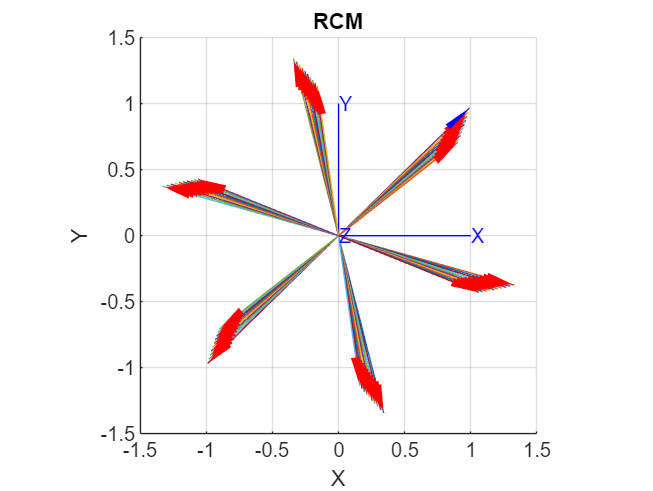

% % % Abschnitt 4: Quaternionen

% Berechne Multiplikation zweier Quaternionen
function Q = calculate_multiplication_quaternion(Q1,Q2)

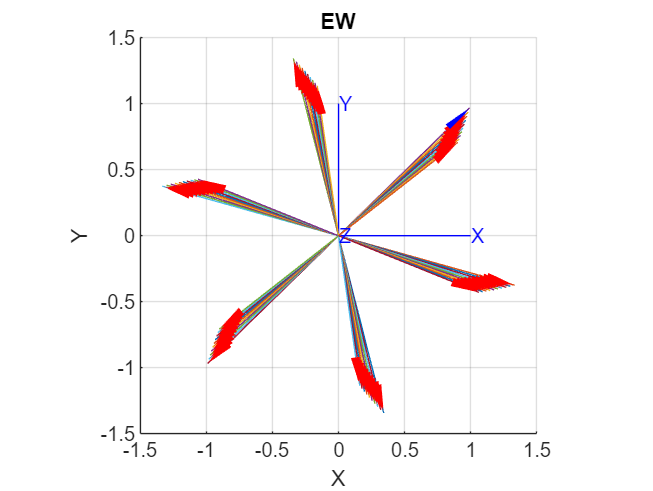

    % perform quaternion multiplication according to script
    Q = [(Q1(1)*Q2(1)-Q1(2:4)*Q2(2:4)'),(Q1(1)*Q2(2:4) + Q2(1)*Q1(2:4) + cross(Q1(2:4),Q2(2:4)))];
end

% Berechne Rotation mit Quaternionen (Q * r * Q_n)
function r = calculate_rotation_quaternion(r,Q)
    r_quaternion = [0, r']; % creat mock quaternion from vektor
    Q_n = [Q(1),-Q(2),-Q(3),-Q(4)]; % create conjugate complex for rotation
    r = calculate_multiplication_quaternion( calculate_multiplication_quaternion(Q,r_quaternion), Q_n ); % perform two mulutiplications for rotation
    r = r(2:4)';
end

function q = calculate_quaternion_from_norm_and_angle(r_norm, angle)
    normAxis = r_norm ./ norm(r_norm);
    q0 = cos(angle / 2);
    q123 = normAxis .* sin(angle / 2);
    q = [q0; q123];
end

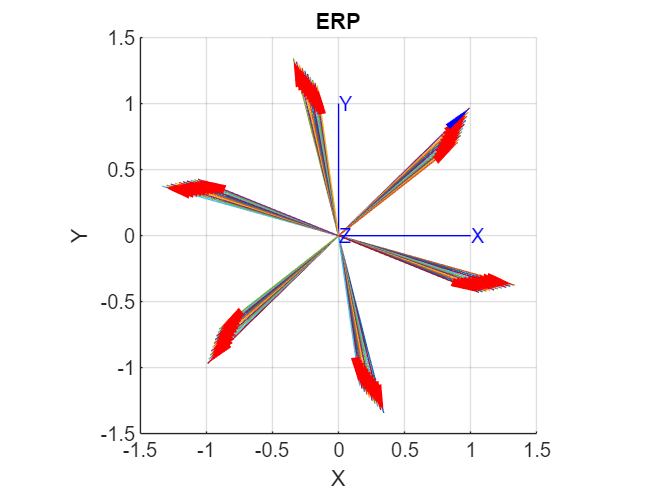


function v_rot = quatrotate_fast(q, v)
    % q : 1x4 Quaternion [w, x, y, z]
    % v : 1x3 Vektor [vx, vy, vz]
    % v_rot : 1x3 Rotierter Vektor

    % Zerlege Quaternion
    w = q(1); 
    x = q(2); 
    y = q(3); 
    z = q(4);

    % Kreuzprodukt-Komponenten
    t = 2 * cross([x y z], v);
    v_rot = v + w * t + cross([x y z], t);
end

function q_out = quatmultiply_fast(q1, q2)

    % q1, q2 sind 1x4 Vektoren: [w, x, y, z]
    w1 = q1(1); x1 = q1(2); y1 = q1(3); z1 = q1(4);
    w2 = q2(1); x2 = q2(2); y2 = q2(3); z2 = q2(4);
    
    q_out = [ w1*w2 - x1*x2 - y1*y2 - z1*z2, ...
              w1*x2 + x1*w2 + y1*z2 - z1*y2, ...
              w1*y2 - x1*z2 + y1*w2 + z1*x2, ...
              w1*z2 + x1*y2 - y1*x2 + z1*w2 ];
end

### 2. Numerische Aspekte & Rechenverhalten

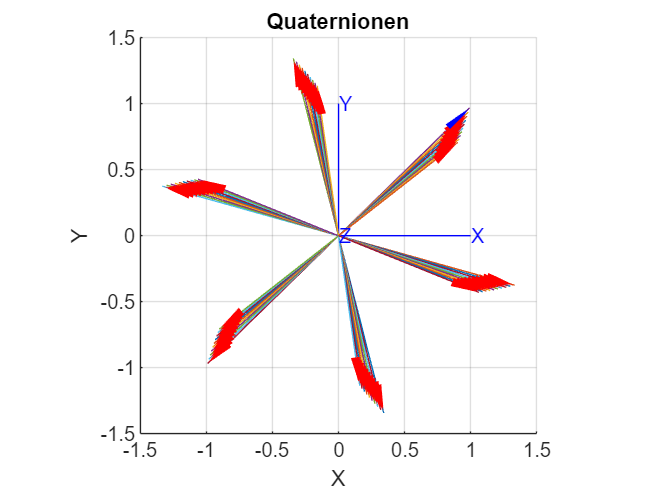

 

if(enable_audio)

    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_02.wav');
    player = audioplayer(y, Fs)
    play(player);
end

Dieser Abschnitt beleuchtet Unterschiede der verschiedenen Verfahren, dabei werden folgende Punkte genauer betrachtet:

- Einfluss von Rundungsfehlern bei mehrfachen Rotationen

- Stabilitätsuntersuchung bei sehr kleinen Winkeln und mehrfachen Rotationen

- Analyse des benötigten Speicherplatzes

- Untersuchung der benötigten Rechenzeit

#### Rundungsfehler bei mehrfachen Rotationen

Zunächst möchten wir veranschaulichen, wie sich Rundungsfehler auf mehrfache Rotationen auswirken. Ein numerisch stabiles Verfahren liefert auch bei kleinen Störungen wie einer begrenzten Genauigkeit oder bei Rundungsfehlern verlässliche und sinnvolle Ergebnisse.

r = [1;
     1;
     0    ];

angle_deg = 60; % 360° mod Winkel muss 0 ergeben!
decimal_places_during_rounding = 6;
amount_of_rotations = 100000;

 

Da numerische Instabilitäten bei moderenen Rechnern aufgrund der hohen Gleitkommapräzision erst nach vielen Rotationen auftreten simulieren wir eine niedrigere Gleitkommapräzision durch Runden der Parameter auf eine definierte Anzahl von Nachkommastellen, angegeben in `decimal_places_during_rounding `und durch obigen Slider definierbar. Bei 64-bit Gleitkommazahlen (double) können ca. 15-17 Nachkommastellen korrekt dargestellt werden, bei 32-bit Gleitkommazahlen (float) sind es 6-7 Nachkommastellen. Testen Sie doch einmal, bei welcher Anzahl von Nachkommastellen Probleme auftreten.

% Setup
plot_every_n_rotations = round(amount_of_rotations / 10, 0);
n_rotations_per_360_deg = 360 / angle_deg;

% Definition der Rotation
R_xyzuvw = rotz(deg2rad(angle_deg));

% Berechnung der benötigten Parametersätze
[u_rcm,v_rcm,w_rcm] = calculate_uvw_from_RCM_rotation_matrix(R_xyzuvw);
R_rcm = calculate_rotation_matrix_RCM(u_rcm,v_rcm,w_rcm);
R_ew = calculate_rotation_matrix_ew(deg2rad(angle_deg),0,0);
q = calculate_q_from_erp_rotation_matrix(R_xyzuvw);
R_erp = calculate_rotation_matrix_erp(q);

% Runden der verschiedenen Parameter
R_rcm = round(R_rcm,decimal_places_during_rounding);
R_ew  = round(R_ew ,decimal_places_during_rounding);
R_erp = round(R_erp,decimal_places_during_rounding);
q = round(q,decimal_places_during_rounding);

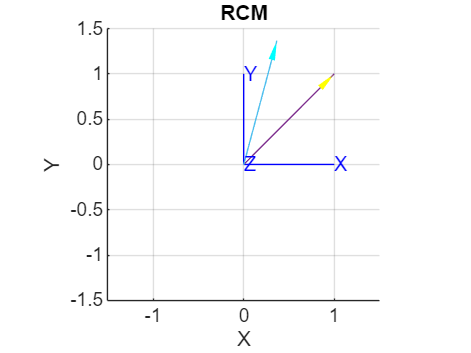

% % % Abschnitt 1: Richtungscosinusmatrix
tranimate(eye(3)); title('RCM'); hold on;
r_rcm = r; first_vector = true;
for z=1:amount_of_rotations 
    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            if first_vector
                plot_arrow([0;0;0], r_rcm, 'b');  % Ersten Vektor in Blau
                first_vector = false;             % Danach alle anderen normal
            else

                plot_arrow([0;0;0], r_rcm, 'r');  % Weitere Vektoren in Rot
            end
        end
        r_rcm = R_rcm * r_rcm;
    end
end
hold off;

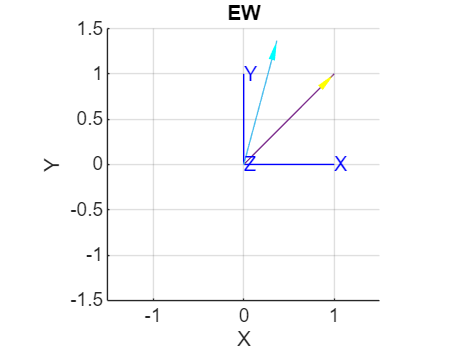

% % % Abschnitt 2: Euler-Winkel
tranimate(eye(3)); title('EW'); hold on;
r_ew = r; first_vector = true;
for z=1:amount_of_rotations 
    for u=1:n_rotations_per_360_deg

        if(mod(z,plot_every_n_rotations)==0)
            if first_vector
                plot_arrow([0;0;0], r_ew, 'b');  % Ersten Vektor in Blau
                first_vector = false;            % Danach alle anderen normal
            else
                plot_arrow([0;0;0], r_ew, 'r');  % Weitere Vektoren in Rot
            end
        end
        r_ew = R_ew * r_ew;
    end
end
hold off;

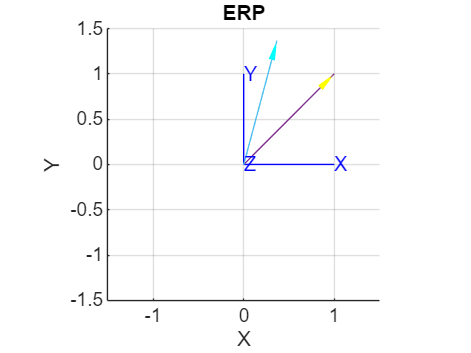

% % % Abschnitt 3: Euler-Rodrigues Parameter

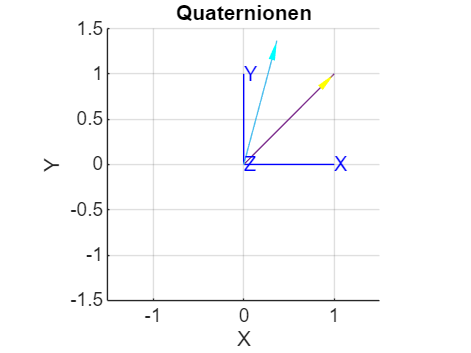

tranimate(eye(3)); title('ERP'); hold on; 
r_erp = r; first_vector = true;
for z=1:amount_of_rotations 
    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            if first_vector
                plot_arrow([0;0;0], r_erp, 'b');  % Ersten Vektor in Blau
                first_vector = false;             % Danach alle anderen normal
            else
                plot_arrow([0;0;0], r_erp, 'r');  % Weitere Vektoren in Rot
            end
        end
        r_erp = R_erp * r_erp;

    end
end
hold off;

% % % Abschnitt 4: Quaternionen
tranimate(eye(3)); title('Quaternionen'); hold on;
r_quat = r'; first_vector = true;

Wenn wir die euklidische Norm des inkrementell rotierten und des direkt rotierten Vektor vergleichen:


for z=1:amount_of_rotations 

Ergeben sich bei Richtungskosinusmatrix: 1.7729e-06


    for u=1:n_rotations_per_360_deg

Ergeben sich bei Euler Winkeln: 1.7729e-06


        if(mod(z,plot_every_n_rotations)==0)

Ergeben sich bei Euler-Rodrigues Parametern: 1.7729e-06


            if first_vector

Ergeben sich bei Quaternionen: 1.7311e-06


                plot_arrow([0;0;0], r_quat, 'b');  % Ersten Vektor in Blau
                first_vector = false;              % Danach alle anderen normal
            else
                plot_arrow([0;0;0], r_quat, 'r');  % Weitere Vektoren in Rot
            end
        end
        r_quat = quatrotate_fast(q,r_quat);
    end
end
hold off;

Wie zu erkennen, gibt es 6 und weniger Nachkommastellen numerische Instabilitäten. Die Vektoren liegen wieder erwarten, bei Rotationen von jeweils 60°, nach einer bestimmten Anzahl von Rotationen nicht mehr übereinander. Aufgrund der kontinuierlichen Multiplikation mit einer "fehlerbehafteten" Rotationsmatrix ist ein Drift in den Ergebnissen wahrzunehmen.

#### Stabilität bei kleinen Winkeln

Im folgenden Absatz stellen wir uns der Frage, ob bei den verschiedenen Methoden eine große Drehung äquivalent zu einer Sequenz vieler kleiner Drehungen ist. Dabei untersuchen wir, inwiefern das Ergebnis einer einzelnen Drehung mit dem Ergebnis einer Komposition vieler Drehungen verglichen werden kann und ob die gewählte Methode der Rotation eine entscheidende Rolle spielt. Dafür wird ein beliebiger Vektor um die Z-Achse rotiert.

Probieren Sie doch einmal unterschiedliche Rotationswinkel, variieren Sie die Anzahl der Inkremente und vergleichen Sie sowohl die Ergebnisse der Methoden untereinander als auch die Abhängigkeit von Gesamtwinkel und Inkrementen.

r = [1;                % zu rotierender Vektor r (Startpunkt)
     1;
     0];
total_angle_deg =30;    % Winkel der um Z rotiert werden soll
n_increments =500000;    % Anzahl der Einzelschritte
n_digits =10;             % Begrenzung der Nachkommastellen 
                                                % (2 = 8bit, 4 = 16bit, 7 = 32bit)

 

% Berechnung der Parameter
incr_angle_deg = total_angle_deg / n_increments;
R_inst = rotz(deg2rad(total_angle_deg));
R_incr = rotz(deg2rad(incr_angle_deg));

% Berechnung der Parameter der verschiedenen Methoden für die "große" Rotation
[u_rcm,v_rcm,w_rcm] = calculate_uvw_from_RCM_rotation_matrix(R_inst);
R_rcm_inst = round(calculate_rotation_matrix_RCM(u_rcm,v_rcm,w_rcm),n_digits);
R_ew_inst = round(calculate_rotation_matrix_ew(deg2rad(total_angle_deg),0,0),n_digits);
q_inst = round(calculate_q_from_erp_rotation_matrix(R_inst),n_digits);
R_erp_inst = round(calculate_rotation_matrix_erp(q_inst),n_digits);

% Berechnung der Parameter der verschiedenen Methoden für die "kleine" Rotation
[u_rcm,v_rcm,w_rcm] = calculate_uvw_from_RCM_rotation_matrix(R_incr);
R_rcm_incr = round(calculate_rotation_matrix_RCM(u_rcm,v_rcm,w_rcm),n_digits);
R_ew_incr = round(calculate_rotation_matrix_ew(deg2rad(incr_angle_deg),0,0),n_digits);
q_incr = round(calculate_q_from_erp_rotation_matrix(R_incr),n_digits);
R_erp_incr = round(calculate_rotation_matrix_erp(q_incr),n_digits);

% % % Abschnitt 1: Richtungscosinusmatrix
tranimate(eye(3)); title('RCM'); hold on; r_rcm = r;

anzahl_iterationen = 40000

plot_arrow([0;0;0],r,'y');

% Berechnung und Darstellung des schrittweise gedrehten Vektors
for z=1:n_increments 
    r_rcm = round(R_rcm_incr * r_rcm,n_digits);
end
plot_arrow([0;0;0],r_rcm,'m');

% Berechnung und Darstellung des direkt gedrehten Vektors
r_rcm_inst = R_rcm_inst * r;
plot_arrow([0;0;0],r_rcm_inst,'c');
hold off;

% % % Abschnitt 2: Euler-Winkel
tranimate(eye(3)); title('EW'); hold on; r_ew = r;
plot_arrow([0;0;0],r,'y');

% Berechnung und Darstellung des schrittweise gedrehten Vektors
for z=1:n_increments 
    r_ew = round(R_ew_incr * r_ew,n_digits);
end
plot_arrow([0;0;0],r_ew,'m');

% Berechnung und Darstellung des direkt gedrehten Vektors
r_ew_inst = R_ew_inst * r; plot_arrow([0;0;0],r_ew_inst,'c'); hold off;

% % % Abschnitt 3: Euler-Rodrigues Parameter
tranimate(eye(3)); title('ERP'); hold on; r_erp = r;
plot_arrow([0;0;0],r,'y');

% Berechnung und Darstellung des schrittweise gedrehten Vektors
for z=1:n_increments 
    r_erp = round(R_erp_incr * r_erp,n_digits);
end
plot_arrow([0;0;0],r_erp,'m');

% Berechnung und Darstellung des direkt gedrehten Vektors
r_erp_inst = R_erp_inst * r; plot_arrow([0;0;0],r_erp_inst,'c'); hold off;

% % % Abschnitt 4: Quaternionen
tranimate(eye(3)); title('Quaternionen'); hold on; r_quat = r';
plot_arrow([0;0;0],r,'y');

% Berechnung und Darstellung des schrittweise gedrehten Vektors
for z=1:n_increments 
    r_quat = round(quatrotate_fast(q_incr,r_quat),n_digits);
end
plot_arrow([0;0;0],r_quat,'m');

% Berechnung und Darstellung des direkt gedrehten Vektors
r_quat_inst = quatrotate_fast(q_inst,r'); plot_arrow([0;0;0],r_quat_inst,'c'); hold off;

Um den direkt rotierten mit dem inkrementell rotierten Vektor zu vergleichen, nutzen wir die Euklidische Norm der beiden Vektoren. Dieser Wert beschreibt den euklidischen Abstand zwischen den Endpunkten der beiden Vektoren. Ein im Vergleich großer Betrag bedeutet einen großen Unterschied. Daraus ergeben sich die folgenden Ergebnisse, anhand derer wir die Methoden vergleichen:

Difference_RCM = norm(r_rcm-r_rcm_inst);
Difference_EW = norm(r_ew-r_ew_inst);
Difference_ERP = norm(r_erp-r_erp_inst);

Betrachten wir zunächst Fall 1, hier wird in jeder Iteration eine Matrix-Vektor-Multipikation durchgeführt.

Difference_Quat = norm(r_quat-r_quat_inst);

Die kürzeste Zeit ist: RCM = 0.0132 Sekunden


disp("Wenn wir die euklidische Norm des inkrementell rotierten und des direkt rotierten Vektor vergleichen:")
disp("Ergeben sich bei Richtungskosinusmatrix: " + Difference_RCM);
disp("Ergeben sich bei Euler Winkeln: " + Difference_EW);
disp("Ergeben sich bei Euler-Rodrigues Parametern: " + Difference_ERP);
disp("Ergeben sich bei Quaternionen: " + Difference_Quat);

Da die Gleitkommagenauigkeit aktueller Computer sehr hoch ist, sind in den Ergebnissen kaum unterschiede erkennbar. Würde man bei jeder Multiplikation und bei jeder Anwendung trigonometrischer Funktionen mit einer reduzierten Gleitkommagenauigkeit arbeiten (was in Matlab nicht realisierbar ist), so wäre eine numerische Instabilität mutmaßlich erkennbar. Auf einen Unterschied zwischen den verschiedenen Methoden kann nicht geschlossen werden.

#### Speicherbedarf

Im anschließenden Codeblock möchten wir untersuchen, wie viel Speicherplatz die Parameter der verschiedenen Verfahren benötigen. Da der Speicherbedarf je Parameter abhängig von dem Datentyp ist, lässt sich der relative Gesamtspeicherbedarf durch die Menge der gespeicherten Parameter abschätzen. 

Im Folgenden wird der benötigte Speicher für $n$ Rotationen bestimmt. Matlab speichert alle Parameter standartmäßig im Format `Double` mit 64-bit.

% Über den folgenden Slider kann bestimmt werden, für welche Anzahl von
% Parametern der benötigte Speicherplatz ausgegeben werden soll.


Die Rechenzeit von EW ist mit 0.0570 um 0.0438 Sekunden (332.84%) größer als RCM.
Die Rechenzeit von ERP ist mit 0.0318 um 0.0186 Sekunden (141.69%) größer als RCM.
Die Rechenzeit von Quaternionen ist mit 0.0406 um 0.0274 Sekunden (208.47%) größer als RCM.


n_parameters =549000;

% % % Abschnitt 1: Richtungscosinusmatrix
RCM_Parameters = zeros(n_parameters, 9);
for z = 1:n_parameters
    RCM_Parameters(z,:) = rand(9,1);
end

% % % Abschnitt 2: Euler-Winkel
EW_Parameters = zeros(n_parameters,3);
for z = 1:n_parameters
    EW_Parameters(z,:) = rand(3,1);
end

% % % Abschnitt 3: Euler-Rodrigues Parameter
ERP_Parameters = zeros(n_parameters,4);
for z = 1:n_parameters
    ERP_Parameters(z,:) = rand(4,1);
end

% % % Abschnitt 4: Quaternionen
Quat_Parameters = zeros(n_parameters,4);
for z = 1:n_parameters
    Quat_Parameters(z,:) = rand(4,1);
end

disp("Array RCM_Parameters ist " + sum(whos('RCM_Parameters').bytes) / 1024^2 + " MB groß.");
disp("Array EW_Parameters ist " + sum(whos('EW_Parameters').bytes) / 1024^2 + " MB groß.");
disp("Array ERP_Parameters ist " + sum(whos('ERP_Parameters').bytes) / 1024^2 + " MB groß.");
disp("Array Quat_Parameters ist " + sum(whos('Quat_Parameters').bytes) / 1024^2 + " MB groß.");

#### Rechenaufwand

Zuletzt möchten wir untersuchen, wie schnell Rotationen mithilfe der vier verschiedenen Ansätze durchgeführt werden können. Hierfür untersuchen wir eine Rotation um alle drei Achsen. 

Wir nehmen an, wir möchten $N$ Iterationen durchführen, das heißt einen gegebenen Vektor $N$ mal rotieren. Es seien die für das jeweilige Verfahren benötigten Parameter gegeben, mit welchen die Rotationsmatrix $R$ berechnet werden kann. Außerdem ist der zu rotierende Vektor $r$ gegeben. Wir betrachten die Herangehensweisen erstmal ohne die meist notwendige Umrechnung von Parametersatz zu Rotationsmatrix. Im späteren Test-Script wird diese Umwandlung natürlich berücksichtigt. Es werden die folgenden zwei Fälle unterschieden:

**Fall 1:** Jede Rotationsmatrix wird einzeln mit dem Vektor multipliziert:


$$\[
r_1 = R_1 \cdot r_0
\]
\[
r_2 = R_2 \cdot r_1 = R_2 \cdot (R_1 \cdot r_0)
\]
\[
\vdots
\]
\[
r_{\text{rotiert}} = R_N \cdot r_{N-1} = R_N \cdot (R_{N-1} \cdot ( \dots (R_1 \cdot r_0)))
\]$$


Wir können für diesen Fall den Aufwand als Anzahl benötigter Operationen berechnen. Dabei ist eine Matrix-Vektor-Multiplikation mit dem Rechenaufwand $n^2$ zu Bewerten, wobei $n$ die Dimension der quadratischen Matrix beschreibt (Quelle: [Wikipedia](https://de.wikipedia.org/wiki/Matrix-Vektor-Produkt)). Diese Matrix-Vektor-Multiplikation wird insgesamt $N$ mal durchgeführt:


$$\[ 
Aufwand = 3^2 \cdot N 
\]$$


**Fall 2:**  Zunächst werden alle Rotationsmatrizen miteinander multipliziert, anschließend der Vektor mit der zusammengefassten Rotationsmatrize multipliziert:


$$\[
R_{\text{gesamt}} = R_1 \cdot R_2 \dots R_N
\]
\[
r_{\text{rotiert}} = R_{\text{gesamt}} \cdot r = (R_1 \cdot R_2 \dots R_N) \cdot r
\]
$$


Auch hier können wir den Rechenaufwand abschätzen. Die Multiplikation zweier quadratischer Matrizen lässt sich mit dem Rechenaufwand $n^3$ bewerten, auch hier ist $n$ wieder die Dimension der quadratischen Matrix (Quelle: [Wikipedia](https://de.wikipedia.org/wiki/Matrizenmultiplikation#Verwendung)). Diese Matrixmultiplikation muss bei $N$Iterationen $N-1$ mal ausgeführt werden. Zuletzt ist noch eine Matrix-Vektor-Multiplikation mit dem Rechenaufwand $n^2$ zu berücksichtigen. Es ergibt sich folgender Aufwand:


$$\[
Aufwand = 3^3 \cdot (N-1) + 3^2
\]$$


Schon jetzt können wir mutmaßen, dass es effizienter ist, eine Rotationsmatrix direkt auf einen Vektor anzuwenden, anstatt zunächst das Produkt aller Rotationsmatrizen zu bilden. Testen wir es doch einmal aus, was vermuten Sie - welcher Ansatz lässt eine Rotation am effizientesten berechnen?

anzahl_iterationen = 40000   % Anzahl an Rotationen, die ausgeführt werden sollen
selection_01 = "F2";                % Was vermuten Sie? Welche Herangehensweise ist effizienter?
selection_02 = "EW";                % Was vermuten Sie? Welcher Ansatz ist am Effizientesten?
 

% Setup
phi = 30; theta = 40; psi = 50;                     % phi, theta und psi als Ausgangsparameter für EW
R_EW = calculate_rotation_matrix_ew(phi,theta,psi); % R als Ausgangsparameter für RCM
q = calculate_q_from_erp_rotation_matrix(R_EW);     % q als Ausgangsparameter für ERP & Quaternionen
R_RCM = angles2rcm(30, 40, 50);

r_init = [1 ; 1 ; 1];                               % Initialvektor

**Fall 1:**

Wir möchten nun zunächst jeweils die Rotationsmatrix aus den gespeicherten Parametern der verschiedenen Verfahren berechnen und diese anschließend auf einen Vektor anwenden. Wir führen $N$ Iterationen durch.

% % % Berechnung der benötigten Rechenzeit RCM
r = r_init; R = R_RCM; 
tic;
for iterationen=1:anzahl_iterationen
    R = R_RCM;
    r_rotiert = R * r;
end

Betrachten wir den Fall 2, hier werden zunächst alle Matrix-Matrix-Multiplikationen durchgeführt.

elapsed_time_rcm_approach_1 = toc;

Die kürzeste Zeit ist: RCM = 0.0198 Sekunden



% % % Berechnung der benötigten Rechenzeit EW
r = r_init; 
tic;
for iterationen=1:anzahl_iterationen
    R = calculate_rotation_matrix_ew(phi,theta,psi);
    r_rotiert = R * r;
end

Die Rechenzeit von EW ist mit 0.0526 um 0.0327 Sekunden (164.79%) größer als RCM.
Die Rechenzeit von ERP ist mit 0.0466 um 0.0268 Sekunden (135.05%) größer als RCM.
Die Rechenzeit von Quaternionen ist mit 0.0249 um 0.0050 Sekunden (25.26%) größer als RCM.


elapsed_time_ew_approach_1 = toc;

% % % Berechnung der benötigten Rechenzeit ERP
r = r_init; q = calculate_q_from_erp_rotation_matrix(R_EW); 
tic;
for iterationen=1:anzahl_iterationen
    R = calculate_rotation_matrix_erp(q);
    r_rotiert = R * r;
end


Ihre Vermutung bzgl. des effizienteren Vorgehens war leider falsch.


elapsed_time_erp_approach_1 = toc;

% % % Berechnung der benötigten Rechenzeit Quaternionen (fast)
r = r_init'; q = calculate_q_from_erp_rotation_matrix(R_EW); 
tic;
for iterationen=1:anzahl_iterationen
    r_rotiert = quatrotate_fast(q, r);

Ihre Vermutung bzgl. des effizientesten Verfahrens für Fall 1 (EW) war leider falsch.


end
elapsed_time_quaternionen_approach_1 = toc;

elapsed_times = [elapsed_time_rcm_approach_1, elapsed_time_ew_approach_1, elapsed_time_erp_approach_1, elapsed_time_quaternionen_approach_1];
[min_time, min_index] = min(elapsed_times);
variable_names = {'RCM', 'EW', 'ERP', 'Quaternionen'};
fprintf('Betrachten wir zunächst Fall 1, hier wird in jeder Iteration eine Matrix-Vektor-Multipikation durchgeführt.');
fprintf('Die kürzeste Zeit ist: %s = %.4f Sekunden\n', variable_names{min_index}, min_time);
for i = 1:length(elapsed_times)
    if i ~= min_index
        differenz = elapsed_times(i) - min_time;
        prozentuale_differenz = (differenz / min_time) * 100;
        fprintf('Die Rechenzeit von %s ist mit %.4f um %.4f Sekunden (%.2f%%) größer als %s.\n', ...
                variable_names{i}, elapsed_times(i), differenz, prozentuale_differenz, variable_names{min_index});
    end
end
fastest_algorithm_time_01 = min_time; fastest_algorithm_name_01 = variable_names{min_index};

**Fall 2:**

In einem zweiten Fall berechnen wir ebenfalls N Rotationsmatrizen aus den gespeicherten Parametern der verschiedenen Verfahren. Diese werden zunächst miteinander multipliziert und erst anschließend auf einen Vektor angewendet. 

% % % Berechnung der benötigten Rechenzeit RCM
r = r_init; R_rcm = R_RCM; 
tic;
R = R_rcm;
for iterationen=1:(anzahl_iterationen-1)
    R = R * R_rcm;
end
r_rotiert = R * r;
elapsed_time_rcm_approach_2 = toc;

% % % Berechnung der benötigten Rechenzeit EW
r = r_init; 
tic;
R = calculate_rotation_matrix_ew(phi,theta,psi);
for iterationen=1:(anzahl_iterationen-1)
    R = R * calculate_rotation_matrix_ew(phi,theta,psi);
end
r_rotiert = R * r;
elapsed_time_ew_approach_2 = toc;

% % % Berechnung der benötigten Rechenzeit ERP
r = r_init; q = calculate_q_from_erp_rotation_matrix(R_EW); 
tic;
R = calculate_rotation_matrix_erp(q);
for iterationen=1:(anzahl_iterationen-1)
    R = R * calculate_rotation_matrix_erp(q);
end
r_rotiert = R * r;
elapsed_time_erp_approach_2 = toc;

% % % Berechnung der benötigten Rechenzeit Quaternionen
r = r_init'; q = calculate_q_from_erp_rotation_matrix(R_EW);
tic;
q = q;
q0 = q;
for iterationen=1:(anzahl_iterationen-1)
    q = quatmultiply_fast(q,q0);
    % q = normalize(q);
end
r_rotiert = quatrotate_fast(q,r)';
elapsed_time_quaternionen_approach_2 = toc;

elapsed_times = [elapsed_time_rcm_approach_2, elapsed_time_ew_approach_2, elapsed_time_erp_approach_2, elapsed_time_quaternionen_approach_2];
[min_time, min_index] = min(elapsed_times);
variable_names = {'RCM', 'EW', 'ERP', 'Quaternionen'};
fprintf('Betrachten wir den Fall 2, hier werden zunächst alle Matrix-Matrix-Multiplikationen durchgeführt.');
fprintf('Die kürzeste Zeit ist: %s = %.4f Sekunden\n', variable_names{min_index}, min_time);
for i = 1:length(elapsed_times)
    if i ~= min_index
        differenz = elapsed_times(i) - min_time;
        prozentuale_differenz = (differenz / min_time) * 100;
        fprintf('Die Rechenzeit von %s ist mit %.4f um %.4f Sekunden (%.2f%%) größer als %s.\n', ...
                variable_names{i}, elapsed_times(i), differenz, prozentuale_differenz, variable_names{min_index});
    end
end
fastest_algorithm_time_02 = min_time; fastest_algorithm_name_02 = variable_names{min_index};

Lassen wir uns nun ausgeben, ob wir mit unseren Vermutungen zur effizientesten Berechnung richtig liegen:

% Fall 1: Fall 1 oder 2 richtig geraten?
if (selection_01 == "F1" && fastest_algorithm_time_01 <= fastest_algorithm_time_02) || ...
   (selection_01 == "F2" && fastest_algorithm_time_02 < fastest_algorithm_time_01)
    fprintf('\nIhre Vermutung bzgl. des effizienteren Vorgehens war richtig!\n');
else
    fprintf('\nIhre Vermutung bzgl. des effizienteren Vorgehens war leider falsch.\n');
end

% Fall 2: Verfahren richtig geraten?
if selection_02 == fastest_algorithm_name_01
    fprintf('Ihre Vermutung bzgl. des effizientesten Verfahrens für Fall 1 (%s) war richtig!\n', selection_02);
else
    fprintf('Ihre Vermutung bzgl. des effizientesten Verfahrens für Fall 1 (%s) war leider falsch.\n', selection_02);
end

Es stellt sich heraus, dass es am effizientesten ist, aufeinanderfolgende Matrix-Vektor-Multiplikationen durchzuführen. Innerhalb dieses Falles ist die Richtungscosinusmatrix das effizienteste Verfahren. Dies liegt daran, dass bei der Anwendung des Verfahrens der Richtungscosinusmatrix die selbige nicht berechnet wird, sondern dass die 9 benötigten Parameter lediglich geladen werden müssen. Bei den übrigen Verfahren müssen zum Teil erst die Rotationsmatrizen aus den gegebenen Parametern berechnet werden. Daraus folgt ein erhöhter Rechenaufwand.

### 3. Interpolationsverhalten

 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_03.wav');
    player = audioplayer(y, Fs)
    play(player);
end

In diesem Abschnitt wird das Verhalten zweier Interpolationsmethoden zur Erzeugung von Laufbahnen zwischen zwei räumlichen Orientierungen untersucht:

- **LERP (Lineare Interpolation)** auf Euler-Winkeln

- **SLERP (Sphärische Interpolation)** auf Quaternionen

Ziel ist es, den qualitativen Unterschied der beiden Methoden visuell und intuitiv darzustellen. Dabei wird der Vektor $\[ 
\vec{r^*} =\left[
\begin{array}{ccc}
1 \\
0 \\
0
\end{array}
\right]
\]$ in den Vektor $\[ 
\vec{r} =\left[
\begin{array}{ccc}
0 \\
1 \\
0
\end{array}
\right]
\]$ überführt, wobei Start- und Endorientierung vorgegeben sind.

Die Start- und Endorientierungen werden in **Euler-Winkeln (ZXZ-Konvention)** angegeben und jeweils in Quaternionen umgerechnet. 

Bei der linearen Interpolation werden **Euler-Winkel** zwischen einer Start- und einer Endorientierung **komponentenweise linear interpoliert**. Das bedeutet, dass jede der drei Rotationskomponenten unabhängig voneinander über eine bestimmte Anzahl an Schritten berechnet wird.


$$\theta (t)=(1-t)\cdot \theta_{start}+t\cdot \theta_{end},mit \ t\in [0,1]$$


Die SLERP-Methode verwendet **Quaternionen** zur Darstellung von Orientierungen. Diese ermöglichen eine **sphärische Interpolation** zwischen zwei Orientierungen. Die Interpolation erfolgt mit **konstanter Winkelgeschwindigkeit**. Die Rotation verläuft **immer auf dem kürzesten Weg** zwischen zwei Orientierungen auf der Sphäre.


$$SLERP(q1,q2,t)=\frac{sin ((1-t)\cdot \Omega )}{sin (\Omega )}q1+\frac{sin (t\cdot \Omega )}{sin (\Omega )}q2 \ mit \ cos(\Omega) = q_1\cdot q_2$$


Der Fokus liegt auf dem **visuellen Vergleich** der entstehenden Trajektorien im Raum:

- **rote Kurve:** resultiert aus der linearen Interpolation der Euler-Winkel

- **blaue Kurve:** resultiert aus der sphärischen Interpolation der Quaternionen

Anhand der geplotteten Trajektorien wird deutlich, dass **SLERP mit Quaternionen** eine **gleichmäßigere und natürlichere Bewegung** ermöglicht – ohne die typischen Probleme von Euler-Winkeln wie Gimbal Lock oder ungleichmäßige Bewegungsgeschwindigkeit.

Bemerkung : Die Umrechnung der Start- und Endorientierungen von **Euler-Winkeln in** Quaternionen (eul2quat) sowie die Berechnung der SLERP (quatinterp, quat2rotm, eul2rotm) werden mit der **Toolbox "Aerospace Toolbox"** realisiert.

% Visueller Vergleich von Euler- und Quaternioneninterpolation anhand von Laufbahnen
% Die Start- und Endorientierungen sind in Euler-Winkeln (ZXZ-Konvention) definiert

 

eul_start = [pi/2, pi/2, 0];           
eul_end   = [0, -pi/2, 0];        

n = 100;
r = [0; 0; 1];  % Vektor zu drehen (Z-Achse)

% Speicher für Laufbahnen initialisieren
traj_euler = zeros(n, 3);
traj_quat  = zeros(n, 3);

% Start- und Endquaternionen berechnen
q_start = eul2quat(eul_start, 'ZXZ');
q_end   = eul2quat(eul_end, 'ZXZ');

for i = 1:n
    t = (i-1)/(n-1);
    
    % Euler-Interpolation
    eul_i = (1 - t)*eul_start + t*eul_end;
    R_euler = eul2rotm(eul_i, 'ZXZ'); 
    traj_euler(i,:) = (R_euler * r)';
    
    % Quaternionen-Interpolation
    q_i = quatinterp(q_start, q_end, t, 'slerp');
    R_quat = quat2rotm(q_i);
    traj_quat(i,:) = (R_quat * r)'; 
end

% Trajektorien plotten
figure('Name', 'Euler vs Quaternion Interpolation');
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Laufbahn der Spitze der Z-Achse während der Rotation');
plot3(traj_euler(:,1), traj_euler(:,2), traj_euler(:,3), 'r--', 'LineWidth', 2);
plot3(traj_quat(:,1), traj_quat(:,2), traj_quat(:,3), 'b-', 'LineWidth', 2);
legend('Euler-Interpolation', 'Quaternionen (SLERP)', 'Location', 'north'); view(3); 
hold off;

### 4. Kommutativität

 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_04.wav');
    player = audioplayer(y, Fs)
    play(player);
end

Rotationen im dreidimensionalen Raum sind nicht kommutativ, weil das Ergebnis davon abhängt, in welcher Reihenfolge die Rotationen durchgeführt werden (weshalb diese bei den Eulerwinkeln vorgegeben ist). Wird ein Körper zuerst um die X-Achse und danach um die Y-Achse dreht, resultiert das in einer anderen Lage, als bei der Rotation um Y- und X-Achse mit den gleichen Parametern. Mathematisch ausgedrückt gilt für Rotationsmatrizen:


$$R_x \cdot R_y \neq R_y \cdot R_x$$


Betrachtet wird im Folgenden der Vektor $\[ 
\vec{r^*} =\left[
\begin{array}{ccc}
1 \\
1 \\
1
\end{array}
\right]
\]$. Dieser wird durch zwei Rotationen im Raum rotiert. Anhand der Regler können Sie die Winkel der Rotation anpassen. Im Beispiel werden die Rotationen auf den Vektor angewendet. Die blauen Vektoren zeigen die Rotation zunächst durch um die in A definierten Winkel, dann um die in B definierten Winkel. Die Rotation zunächst um B und dann um A wird mit grünen Vektoren veranschaulicht.

Dreht man in beiden Fällen (A und B) um die gleiche Achse, treffen sich die resultierenden Vektoren wieder. Probieren Sie dies doch einmal aus!

angleAZ = 0;
angleAY = -20;
angleAX = 15;


angleBZ = 15;
angleBY = 0;
angleBX = 35;

 

function drawAngle3D(v1, v2, colour)
    % Normiere die Vektoren
    u1 = v1 / norm(v1);
    u2 = v2 / norm(v2);

    % Winkel zwischen den Vektoren
    theta = acos(dot(u1, u2));

    % Normalenvektor der Ebene, in der der Winkelbogen liegt
    n = cross(u1, u2);

    % Orthonormales Koordinatensystem in der Ebene
    x_axis = u1;
    y_axis = cross(n, x_axis);
    y_axis = y_axis / norm(y_axis);

    % Winkelbogen erzeugen
    r = 0.5 * min(norm(v1), norm(v2)); % Dynamischer Radius
    n_points = 100;
    angles = linspace(0, theta, n_points);
    arc = zeros(3, n_points);
    for i = 1:n_points
        arc(:,i) = r * (cos(angles(i)) * x_axis + sin(angles(i)) * y_axis);
    end

    % Winkelbogen zeichnen
    plot3(arc(1,:), arc(2,:), arc(3,:), colour, 'LineWidth', 1);

    % Winkeltext anzeigen
    % text_pt = 1.1 * arc(:, round(n_points/3));
    % text(text_pt(1), text_pt(2), text_pt(3), ...
    %    sprintf('\\theta = %.1f°', theta_deg), 'FontSize', 12);
end

r_rot0 = [1,0,1];
r_rot0 = r_rot0/norm(r_rot0);

RrotA = angles2rcm(angleAZ, angleAY, angleAX);
RrotB = angles2rcm(angleBZ, angleBY, angleBX);

tranimate(eye(3)); title('Nicht-Kommutativität von Rotationen'); hold on;
plot_arrow([0;0;0],r_rot0,'r');

r_rotA = r_rot0 * RrotA;
r_rotAB = r_rot0 * RrotA * RrotB;
r_rotAB = r_rotAB/norm(r_rotAB);

plot_arrow([0;0;0],r_rotA,'b'); 
plot_arrow([0;0;0],r_rotAB,'b');

r_rotB = r_rot0 * RrotB;
r_rotBA = r_rot0 * RrotB * RrotA;
r_rotBA = r_rotBA/norm(r_rotBA);

plot_arrow([0;0;0],r_rotB,'g'); p.LineWidth = 3; 
plot_arrow([0;0;0],r_rotBA,'g');

drawAngle3D(r_rot0,r_rotA, '--b');
drawAngle3D(r_rot0,r_rotB, '--g');
drawAngle3D(r_rotA,r_rotAB, '--b');
drawAngle3D(r_rotB,r_rotBA, '--g');

p1 = plot3(NaN, NaN, NaN, 's', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); p2 = plot3(NaN, NaN, NaN, 's', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b'); p3 = plot3(NaN, NaN, NaN, 's', 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');
legend([p1, p2, p3], {'Ursprungsvektor', 'Rotation A + B', 'Rotation B + A'});
hold off;

Die resultierenden Vektoren können große Unterscheide aufweisen. Denoch kann man nicht in richtiges und falsches Ergebniss unterscheiden. Die Reihenfolge der Drehung muss durch die Konvention festgelegt werden. (vgl. Eulerwinkel)

delta = acos(dot(r_rotAB, r_rotBA))*180/pi;
fprintf('\n Der Unterschied zwischen den Vektoren beträgt %.2f°\n', delta);

### 5. Gimbal Lock und Singularität

 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_05.wav');
    player = audioplayer(y, Fs)
    play(player);
end

#### Gimbal Lock

Gimbal Lock bezeichnet ein Problem bei der Verwendung von **Euler-Winkeln** zur Darstellung von Rotationen im dreidimensionalen Raum.

Euler-Winkel verwenden aufeinanderfolgende Drehungen, um eine Rotation zu beschreiben. Dabei kann es vorkommen, dass zwei Rotationsachsen **parallel** werden. In einem solchen Fall verliert man **einen Freiheitsgrad**, da zwei Rotationen um dieselbe Achse keine unabhängige Bewegung mehr ermöglichen.

Das führt zu unerwarteten Bewegungseinschränkungen, unklaren oder instabilen Orientierungen, Problemen bei der Interpolation oder Steuerung eines Roboters.

Mit der ZXZ-Konvention tritt dieses Phänomen auf, wenn $\theta\ mod\ \pi =0$, dann liegen die beiden Z-Achsen aufeinander, was zu einem Verlust eines Freiheitsgrads führt.

Die Eulerwinkel werden in der Roboterkonstruktion häufig genutzt, um Roboterhände aufzubauen. Wir stützen uns auf diese Konfiguration, um das Problem des Gimbal Locks zu demonstrieren. Die letzten drei Achsen des Roboters repräsentieren die Roboterhand. Man stellt fest, dass, wenn die Rotation um Achse 5 gleich null ist, die Rotationen um Achse 4 und Achse 6 denselben Effekt haben.

% Erstellung der Robotergelenke
L(1) = Link('d', 0.5, 'a', 0,'alpha',pi/2);  
L(2) = Link('d', 0,'a', 0.5,'alpha',0);    
L(3) = Link('d', 0,'a', 0,'alpha',pi/2); 
L(4) = Link('d', 0.5,'a', 0,'alpha',-pi/2); % Erste Achse der Roboterhand

Liegt der Fokus auf keinen Singularitäten oder Gimbal Lock, empfiehlt sich die Verwendung von Richtungskosinusmatrizen oder Quaternionen.

L(5) = Link('d', 0,'a', 0,'alpha',pi/2); % Zweite Achse der Roboterhand
L(6) = Link('d', 0.5,'a', 0,'alpha',0);     % Dritte Achse der Roboterhand


% Erstellung der Roboter (vier identische Roboter zur Darstellung der
% verschiedenen Fälle)
robot1 = SerialLink(L, 'name', 'Robot 1');
robot2 = SerialLink(L, 'name', 'Robot 2');
robot3 = SerialLink(L, 'name', 'Robot3');
robot4 = SerialLink(L, 'name', 'Robot4');

%Definition der Start-und Endkonfigurationen
start = [0 deg2rad(50) deg2rad(50) 0 0 0]; 
end1 = [0 deg2rad(50) deg2rad(50) deg2rad(90) deg2rad(90) 0];   % Erste Konfiguration ohne Gimbal lock
end2 = [0 deg2rad(50) deg2rad(50) 0 deg2rad(90) deg2rad(90)];   % Zweite Konfiguration ohne Gimbal lock
end3 = [0 deg2rad(50) deg2rad(50) deg2rad(90) 0 0];             % Erste Konfiguration mit Gimbal lock
end4 = [0 deg2rad(50) deg2rad(50) 0 0 deg2rad(90)];             % Zweite Konfiguration mit Gimbal lock

% Erstellen einer neuen Figur

Aufgrund der gegebenen Gewichtung, empfiehlt sich die Verwendung von Quaternionen.

figure;

Erstens stellt man fest, dass außerhalb einer Singularität (d. h. wenn $\theta \;\not= 0$) die Achsen 4 und 6 unterschiedliche Auswirkungen auf die Position des TCP haben:

% Erstellung der Abbildungen - Ohne Gimbal Lock
subplot(2,2,1);
robot1.plot(end1);
title('[$\phi = 90, \theta = 90, \psi= 0$]','Interpreter','latex');

subplot(2,2,2);
robot2.plot(end2);
title('[$\phi = 0, \theta = 90, \psi= 90$]','Interpreter','latex');

Im Fall eines Gimbal Lock ($\theta \;\not= 0$) hat eine Rotation um Achse 4 den gleichen Effekt wie eine gleichwertige Rotation um Achse 6. Dadurch geht ein Freiheitsgrad verloren:

% Erstellung der Abbildungen - Mit Gimbal Lock
subplot(2,2,3);
robot3.plot(end3);
title('[$\phi = 90, \theta = 0, \psi= 0$]','Interpreter','latex');

subplot(2,2,4);
robot4.plot(end4);
title('[$\phi = 0, \theta = 0, \psi= 90$]','Interpreter','latex');

#### Euler-Rodrigues Parameter: Singularität

Die ERP beschreiben eine Rotation im Raum mithilfe eines Normalenvektors $n$ sowie einem Winkel $\varphi$, deren Darstellung auch als ERP $q$ möglich ist. Um die nachfolgende Erklärung besser zu verstehen, werden im Folgenden nochmals die Zusammenhänge zwischen Normalenvektor, Winkel und ERP dargestellt.


$$\[
\varphi = 2 \arccos(q_0), \quad
n = \frac{1}{\sin(\varphi/2)} \left[ q_1 \, q_2 \, q_3 \right]^\top, \quad
q_0 = \cos\left( \frac{\varphi}{2} \right), \quad
\left[ q_1 \, q_2 \, q_3 \right]^\top = n \cdot \sin\left( \frac{\varphi}{2} \right), \quad
q = \left[ q_0 \, q_1 \, q_2 \, q_3 \right]^\top
\]$$


Eine Singularität tritt nun auf, wenn der Winkel $\varphi =180\degree$ ist. Für $q_0 =\cos \left(\frac{\pi }{2}\right)$ ergibt sich ein diesem Fall ein $q_0 =0$. Nun muss man zwei Fälle betrachten. 

**Fall 1: **Sind die Parameter $q = \left[ q_0 \, q_1 \, q_2 \, q_3 \right]^\top$ gegeben, so ist die Rotationsachse durch $q_1 ,q_2 ,q_3$ gegeben. Eine Rotation um 180° ist möglich. Dies zeigen wir im folgenden Beispiel.

 

phi = 180                   % Rotationswinkel von 180°

n = [ 0 ; 0 ; 1 ]                                   % Wir definieren einen Normalenvektor (Drehung um z-Achse)
q0 = cos(deg2rad(phi)/2)                            % Das Ergebnis für q0 berechnet aus dem Winkel phi 
                                                    % ergibt sich bei einem Rotationswinkel von
q0 = round(q0,6)                                    % 180° zu 0
q123 = n * sin(deg2rad(phi)/2)                      % Wir berechnen q123 und damit die übrigen benöigten Parameter
R = calculate_rotation_matrix_erp([q0;q123])        % Nun können wir die Rotationsmatrix berechnen

figure;
tranimate(eye(3)); title('ERP - Drehung um 180° mit definiertem Normalenvektor'); hold on; r = [ 1 ; 0 ; 0 ];
plot_arrow([0;0;0], r, 'b');                        % Vektor vor Drehung in Blau
plot_arrow([0;0;0], R * r, 'r');                    % Vektor nach Drehung in Rot
hold off;

**Fall 2**: Es sei eine Rotationsmatrix für eine Rotation um 180° gegeben. Wir möchten nun unseren Parametersatz $q$ berechnen. Damit wir besser nachvollziehen können, was nun passiert, sind im Folgenden nochmal die benötigten Gleichungen dargestellt:


$$\[
q_0 = \sqrt{ \frac{\text{Spur}(A)+ 1}{4} }, \quad q_1 = \frac{r_{32} - r_{23}}{4q_0}, \quad q_2 = \frac{r_{13} - r_{31}}{4q_0}, \quad q_3 = \frac{r_{21} - r_{12}}{4q_0}
\]$$


Da sich $q_0 =0$ ergibt, ist leicht nachzuvollziehen, warum keine Lösungen für $q_1 ,q_2 ,q_3$ existieren. Die Rotationsachse $n$ lässt sich nicht eindeutig bestimmen. Viel mehr existieren unendlich viele Lösungen für die Rotationsachse $n$ und damit eine Drehung um 180°. Genau dies bezeichnen wir im Fall der Euler-Rodrigues Parameter als **Singularität**. Im folgenden Beispiel wird dies nochmals deutlich: 

R = R;                                              % Wir nutzen nun die eben berechnete Rotationsmatrix als Ausgangswert
q = calculate_q_from_erp_rotation_matrix(R)         % Nun berechnen wir unseren Parametersatz q. Für q1 bis q3 finden sich 
                                                    % keine Lösungen. Eine Berechnung der Rotationsachse ist nicht möglich.  

Ebenfalls interessant ist in diesem Zusammenhang die Frage: Was passiert, wenn man um Winkel nahe 180° rotiert?

Probieren wir es doch einmal aus, indem wir den Rotationswinkel, welcher in Fall 1 definiert wird, leicht abändern. Bei Winkeln nahe 180° kann es leicht zu numerischen Instabilitäten kommen. Diese simulieren wir durch die Addition einer Zufallszahl zwischen 0 und 0,1. Betrachtet man nun den resultierenden Plot, insbesondere in der 3D-Ansicht, so sieht man, dass sich die Normalenvektoren stark voneinander unterscheiden. In einer realen Anwendung ist dies natürlich nicht gewünscht, sodass Rotationen um ~180° eher in zwei oder mehrere Rotationen um kleinere Winkel, aber dafür definierte Rotationsachsen aufgeteilt werden sollten.

Hinweis: Rotationswinkel auf Winkel nahe 180° abändern! Anhand der Zwischenergebnisse für $q$ können wir gut nachvollziehen, was passiert.

q = q                                               % Wir nutzen das eben bestimmte q
q_instability_1 = q + ( 0.1 .* rand(1,1) )          % Nun simulieren wir eine numerische Instabilität, indem wir
q_instability_2 = q + ( 0.1 .* rand(1,1) )          % extrem kleine Änderungen an unseren Parametern vornehmen
q_instability_3 = q + ( 0.1 .* rand(1,1) )

figure;
tranimate(eye(3)); title('ERP - Drehung um 180° mit definiertem Normalenvektor'); hold on; r = [ 1 ; 0 ; 0 ];
plot_arrow([0;0;0], r, 'b');                                                        % Initial Vektor vor Drehung in Blau
plot_arrow([0;0;0], calculate_rotation_matrix_erp(q) * r, 'r');                     % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_rotation_matrix_erp(q_instability_1) * r, 'r');       % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_rotation_matrix_erp(q_instability_2) * r, 'r');       % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_rotation_matrix_erp(q_instability_3) * r, 'r');       % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_n_from_erp_q(q_instability_1), 'o');       % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_n_from_erp_q(q_instability_2), 'o');       % Vektor nach Drehung in Rot
plot_arrow([0;0;0], calculate_n_from_erp_q(q_instability_3), 'o');       % Vektor nach Drehung in Rot
hold off;

### 6. Zusammenfassung und Empfehlung

 

if(enable_audio)
    try
        pause(player);
    catch
        0;
    end
    [y, Fs] = audioread('Podcast_Robotertechnik_Chapter_06.wav');
    player = audioplayer(y, Fs)
    play(player);
end

Abschließend möchten wir uns die vorgestellten Methoden und ihre Vor- und Nachteile nochmals kurz in Erinnerung rufen und zusammenfassen.

**1. Richtungskosinusmatrix (RCM)**

Eine 3x3-Matrix, deren Spalten die Einheitsvektoren des rotierten Koordinatensystems im ursprünglichen Basissystem darstellen.

        + eindeutig und direkt

        + kein Gimbal Lock

        + klare Definition bei Kombinationen von Rotationen

        - nicht kompakt (9 Werte)

        - Interpolation von Matrizen ist schwierig und unnatürlich

Anwendung: Als eindeutige Referenzdarstellung in Systemen, in denen absolute Klarheit erforderlich ist. Wenn die Rotationsmatrix bereits bekannt ist und häufig Vektoren transformiert werden müssen. In der grundlegenden Kinematik und Dynamik zur Formulierung von Transformationsketten.

**2. Euler-Winkel**

Drei Winkel (z.B. $\phi ,\theta ,\psi$), die drei aufeinanderfolgende Drehungen um festgelegte Achsen (z.B. ZXZ-Konvention) beschreiben.

        + sehr kompakt (3 Werte)

        + intuitiv für Menschen

        - Gimbal Lock möglich

        - Drehreihenfolge entscheidend

        - Interpolation oft problematisch

        - Uneindeutigkeit und nicht immer umkehrbar

Anwendung: Für Benutzerschnittstellen (Eingabe/Anzeige von Orientierungen). Zur Beschreibung der Orientierung von Flugzeugen (Roll-, Nick-, Gierwinkel), wobei die Singularitäten beachtet werden müssen.

**3. Euler-Rodrigues-Parameter (ERP)**

Ein Satz von vier Parametern, der auf dem Konzept einer einzelnen Drehung um eine spezifische Achse (Vektor n) um einen bestimmten Winkel (ϕ) basiert. Die vier Parameter beinhalten die gesamte benötigte Information.

        + kompakt (4 Werte)

        + kein Gimbal Lock

        - aber Singularität bei 180°-Drehungen

        - weniger intuitiv

Anwendung: Wenn eine kompakte, Gimbal-Lock-freie Darstellung erforderlich ist und bei denen die 180°-Singularität berücksichtigt und ggf. umgangen werden kann. Oft als theoretische Grundlage oder als Zwischenschritt bei der Arbeit mit Quaternionen, da eine enge mathematische Verwandtschaft besteht.

**4. Quaternionen**

Eine Erweiterung der komplexen Zahlen, bestehend aus vier Komponenten (einem Skalarteil und drei Imaginärteilen = einem Vektorteil). Für Rotationsbeschreibungen sind sie mathematisch äquivalent zu den Euler-Rodrigues-Parametern.

        + kompakt (4 Werte)

        + kein Gimbal Lock

        + effiziente Rotation und Interpolation (SLERP)

        - schwer verständlich

        - wie bei ERP Singularität bei 180°-Drehungen (softwaretechnisch abfangbar)

Anwendung: Bevorzugte Methode in vielen modernen Anwendungen wie: Robotik, Luft- und Raumfahrttechnik und Computerspielen. Immer dann, wenn glatte Animationen und Trajektorien, hohe numerische Stabilität und Effizienz bei der Verknüpfung von Rotationen entscheidend sind.

Nun noch eine übersichtliche Gegenüberstellung aller Methoden in Form der folgenden Tabelle. Dabei stehen 2 Plus-Zeichen für "sehr gut" und zwei Minus-Zeichen für "sehr schwach"; die Null bedeutet "neutral".

#### **Entscheidungshilfe**

Zuletzt möchten wir hier eine kurze Entscheidungshilfe bieten. Dafür gewichten Sie bitte die folgenden Faktoren und lassen sich daraufhin unsere Empfehlung für eine Methode ausgeben.

choice = 4;
Fokus = ["schneller Berechnung", "geringem Speicherbedarf", "guter Interpolation", "keinen Singularitäten oder Gimbal Lock"];
Texts = ["Richtungskosinusmatrizen","Euler-Winkeln","Quaternionen","Richtungskosinusmatrizen oder Quaternionen"];
fprintf("Liegt der Fokus auf %s, empfiehlt sich die Verwendung von %s.", [Fokus(choice), Texts(choice)]);

Alternativ können hier die in der Tabelle gelisteten Kriterien gewichtet werden (von 0 bis 5). Daraufhin wird die beste Option gemäß der Gewichtung ausgegeben:

Rechenaufwand             =1;
Interpolationsverhalten   =1;
Singularitaeten           =1;
Speicherbedarf            =1;

 

Weights = [Rechenaufwand;Interpolationsverhalten;Singularitaeten;Speicherbedarf];
Values = [ 2,-2,-1, 0;
          -2,-1, 0, 2;
           2,-2, 1, 1;
          -2, 2, 1, 1];
Values = Values .* Weights;
Sums = sum(Values,1);
[Rating, Index] = max(Sums);
Texts = ["Richtungskosinusmatrizen","Euler-Winkeln","Euler-Rodrigues-Parameter","Quaternionen"];
fprintf("Aufgrund der gegebenen Gewichtung, empfiehlt sich die Verwendung von %s.", [Texts(Index)]);

**Wir hoffen, dass Sie mithilfe dieses Skripts die unterschiedlichen Methoden der Rotation besser verstanden haben und sowohl deren Vor- als auch Nachteile kennen. So können Sie das geeigneteste Werkzeug für ihre gegebene Aufgabe wählen!**

*(erstellt von Mika Grüner, Luka Hrstic, Lukas Pelz und Marie Winkler)*